## Explore the parameters for the gas/star fractions from  TNG100

 we generted fits for double gaussian based on histograms of the fgs value. The bin number/size of the histogram affects the  result  We want to see how the fit changes with histogram bin number/size

## loading the data


global DEFAULT_MATFILE_DIR


load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_99_TNG100.mat'])



binEdge=[9 9.2500 9.5000 9.7500 10 10.2500 10.5000 10.7500 11 11.2500 11.5000];
be=9:0.25:11.5;


fgs=-5:0.001:1.5;

## plot pdf's for different histogram bins 

 we plot the resultign PDFs for different stellar mass bins from the  different fits. Changes appear to be very small. 

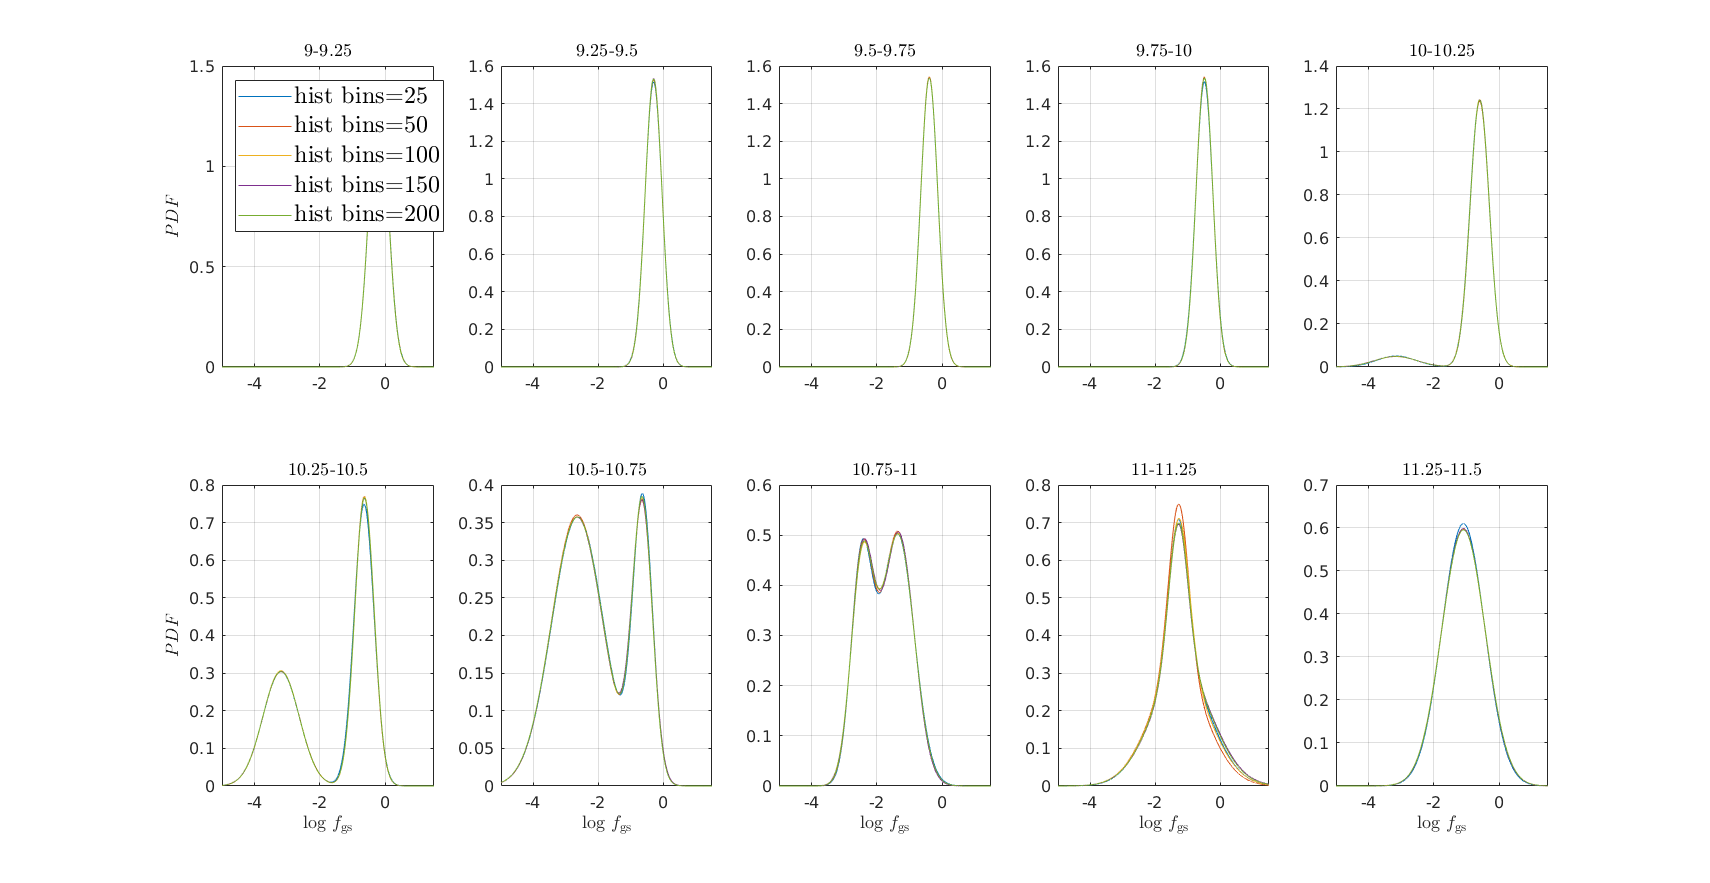



hf=figure('color','w','position',[83 433 1710 883]);




for i=1:length(ft(1).mu1)
    h=[];
    
    pdf1=zeros(length(ft),length(fgs));
    for k=1:length(ft)
        pdf=ft(k).a1(i).*exp(-0.5.*((fgs-ft(k).mu1(i))./ft(k).sig1(i)).^2) + ...
            ft(k).a2(i).*exp(-0.5.*((fgs-ft(k).mu2(i))./ft(k).sig2(i)).^2);
        pdf1(k,:)=pdf./trapz(fgs,pdf);
        
    end
    
    %figure(hf)
    subplot(2,5,i)
    ax=gca;
    
    
    for k=1:length(ft)
        tag=['hist bins=' num2str(ft(k).histBinNum)];
        h(k)=plot(fgs,pdf1(k,:),'Displayname',tag);
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','NorthWest');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    xlim([-5 1.5])
    if i>5
        xlabelmine( '$\log\,f_\mathrm{gs}$');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( '$PDF$');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

## plot fit parameters for different histogram bins

Here we examine the results more closely - follow the parameters themselves as bin number/size is changed. In the mass bins where the fit produced a single gaussian we ignore the other fit results. 

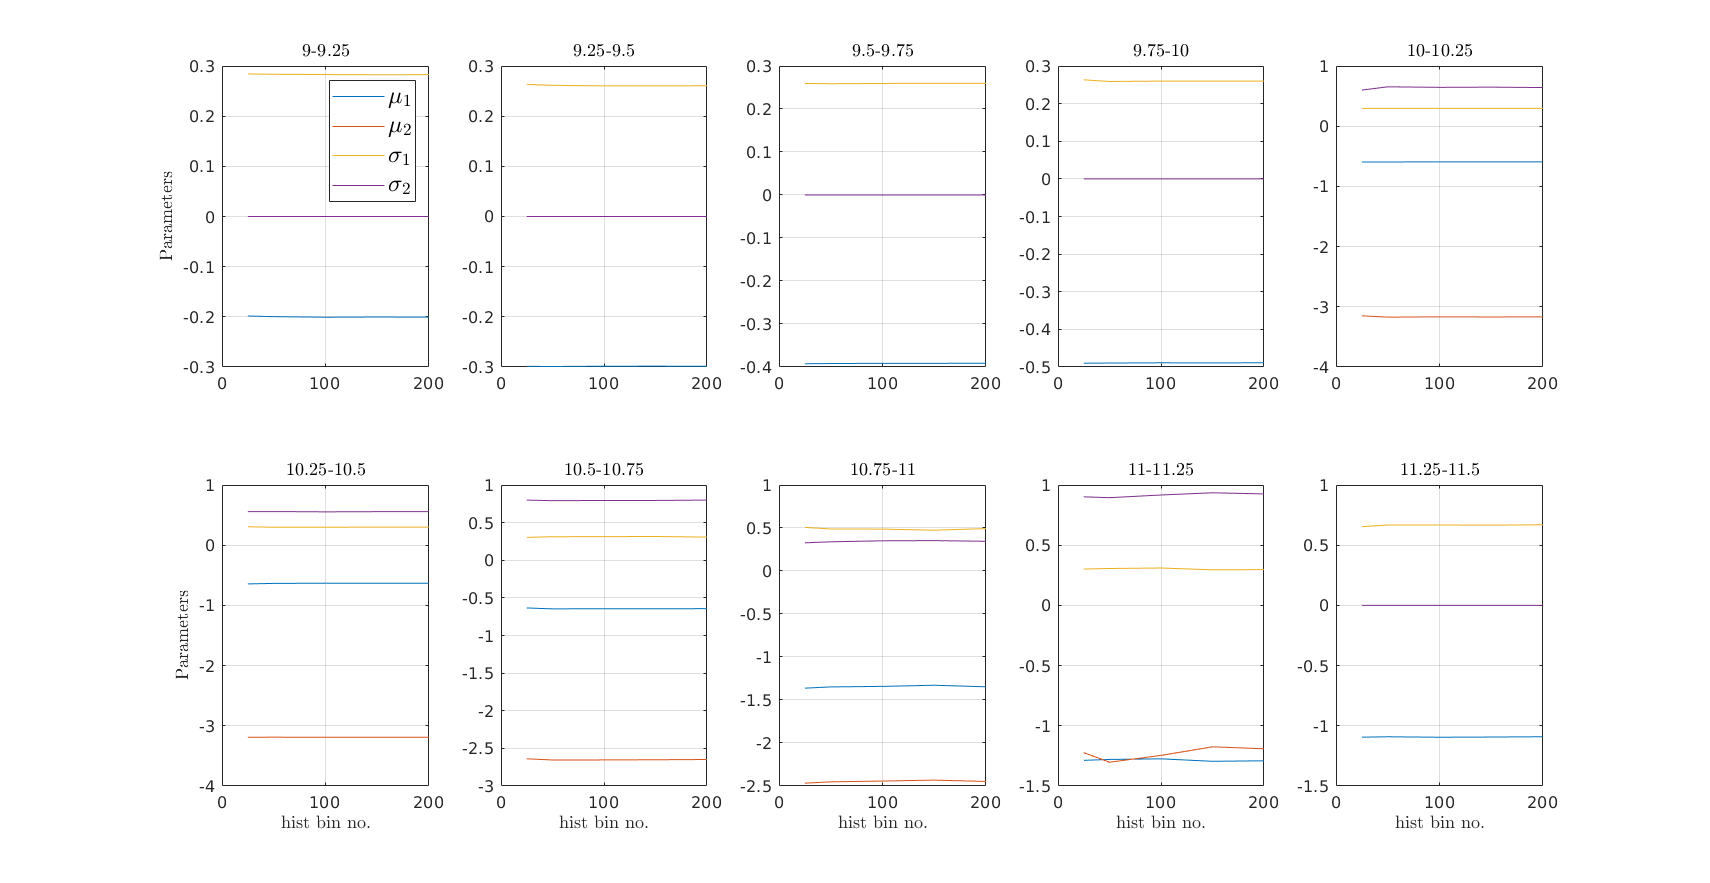


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
 
    
 
    subplot(2,5,i)
    ax=gca;
        
    for k=1:4
        h(k)=plot(xx,pars(:,k),'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

 Plot the amplitude values - these go down since the bin size is

 decreasing

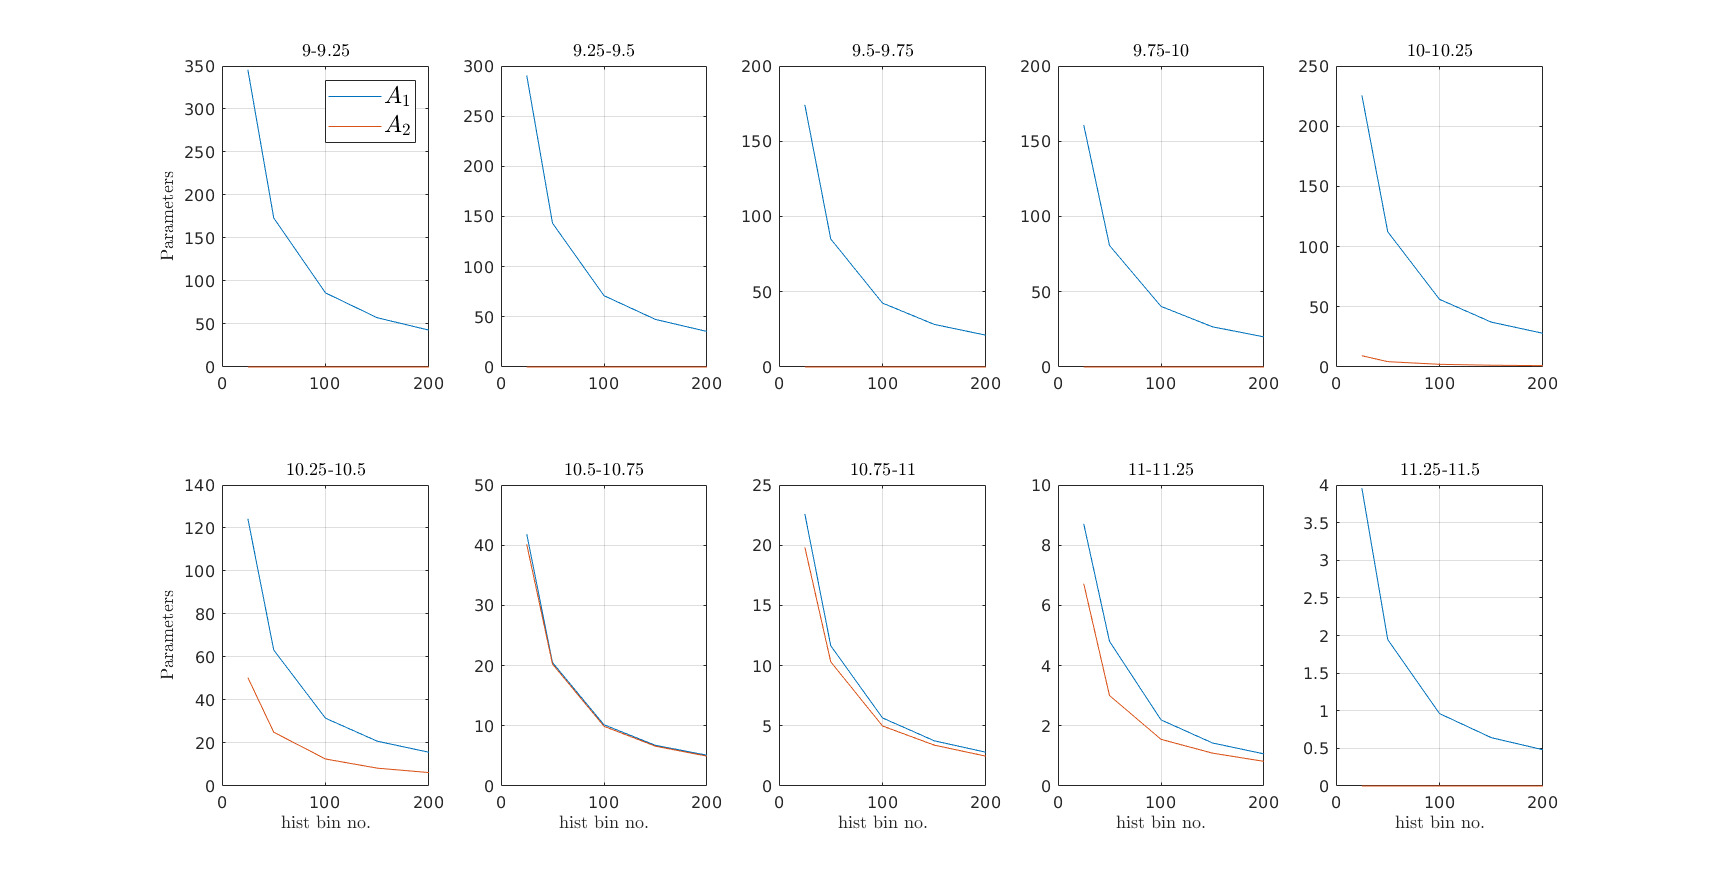


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
   
 
    subplot(2,5,i)
    ax=gca;
        
    for k=5:6
        h(k-4)=plot(xx,pars(:,k),'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

Now plot the fractional values for the fit parameters 

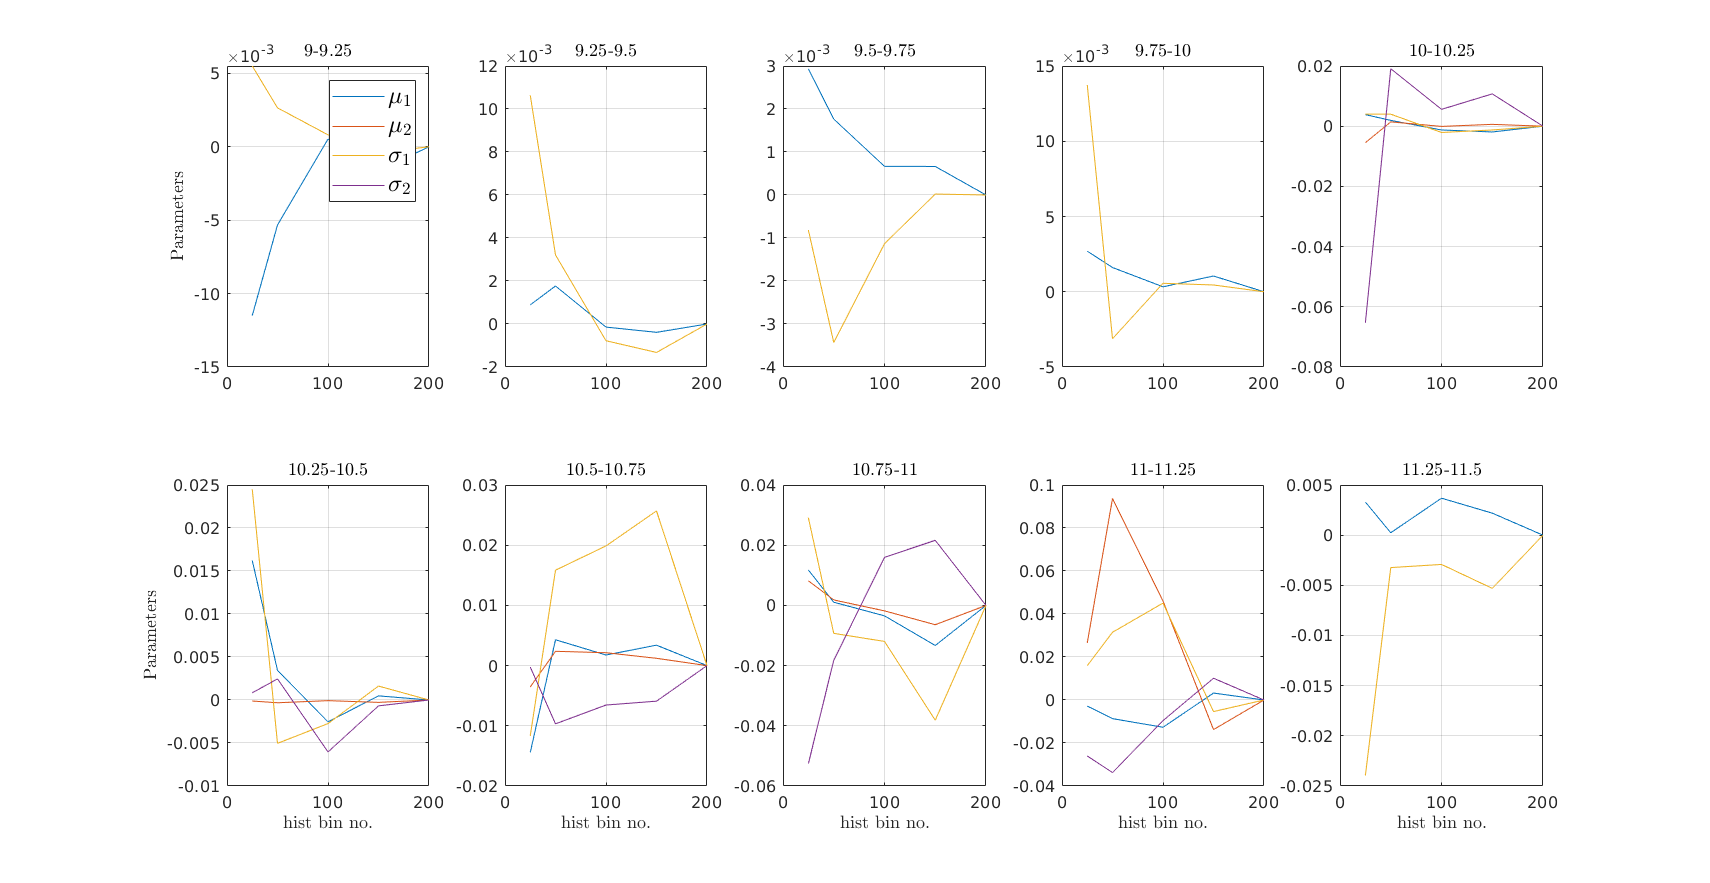


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
 
    
 
    subplot(2,5,i)
    ax=gca;
        
    for k=1:4
        h(k)=plot(xx,pars(:,k)./pars(end,k)-1,'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

## conclusion - the fits are by and large consistent even for low bin number histograms, but there are some weird flukes we should be carful of, using the 200 bin fit is probably best. 